load santafe.mat

% orderlist = [2 5 10 20 40 80 100 120 140];
orderlist = [1 2 5 10 20 50 65 80 100 120 140];
n = length(orderlist);

gamlist = zeros(1,n);
sig2list = zeros(1,n);

RMSE_order = zeros(1,n);
MAE_order = zeros(1,n);

for i = 1:n
    
    order = orderlist(i);
    
    % Prepare the training data
    X = windowize(Z, 1:(order + 1));    
    Y = X(:, end);
    X = X(:, 1:order);
    
    % tune the gam and sig2 with training data
    model = { X , Y , 'f', [], [],'RBF_kernel'};
    algorithm = 'simplex';
    [gam , sig2, cost] = tunelssvm(model, algorithm, 'crossvalidatelssvm',{10, 'mae'});
    
    % notedown the tuned gam and sig2 for each order number 
    gamlist(i) = gam;
    sig2list(i) = sig2;
    
    
    % train the model with tuned gam and sig2
    [alpha, b] = trainlssvm({X, Y, 'f', gam, sig2,'RBF_kernel'});
    
    % prepare the test data for prediction
    Xs = Z(end - order + 1:end , 1);
    nb = 200;
    
    % make the prediction and calucate the prediction performance with MSE
    % and correlation;
    prediction = predict({X, Y, 'f', gam, sig2,'RBF_kernel'}, Xs, nb);
    
%     figure;
%     
%     hold on;
%     plot_title = ['Prediction with order: ' num2str(order) ' gam: ' num2str(gam) ' sig2: ' num2str(sig2)];
%     title(plot_title);
%     plot(Ztest, 'k');
%     plot(prediction, 'r');
%     hold off;
    
    RMSE_order(i) = sqrt(mean((Ztest-prediction).^2));
    
    MAE_order(i) = mean(abs((Ztest-prediction)));
    
%     R = corrcoef(Ztest,prediction);
%     R_order(i) = R(1,2);
%     

end 


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2557.3147
                                          [sig2]        14.0841
                                          F(X)=         28.3509
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2557.3147      14.084108

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     2.833989e+01     9.0467        2.6450      initial 
     2           4     2.833989e+01     9.0467        2.6450      reflect 
     3           6     2.833244e+01     10.2467        2.6450      reflect 
     4          10     2.833244e+01     10.2467        2.6450  

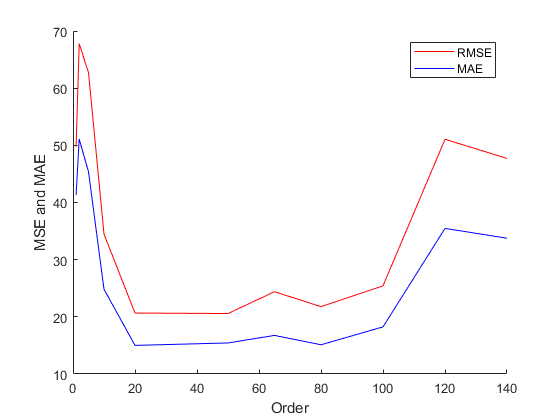


% plot the order vs MSE and Correlation 
figure 
hold on
xlabel('Order')
ylabel('MSE and MAE')
plot(orderlist, RMSE_order,'r');
plot(orderlist, MAE_order,'b');
legend('RMSE','MAE')
hold off

% [~, index] = min(MAE_order);
index = 6;
opt_order = orderlist(index);
disp(opt_order);

    50



opt_gam = gamlist(index);
disp(opt_gam);

  635.7314



opt_sig2 = sig2list(index);
disp(opt_sig2);

   22.9585



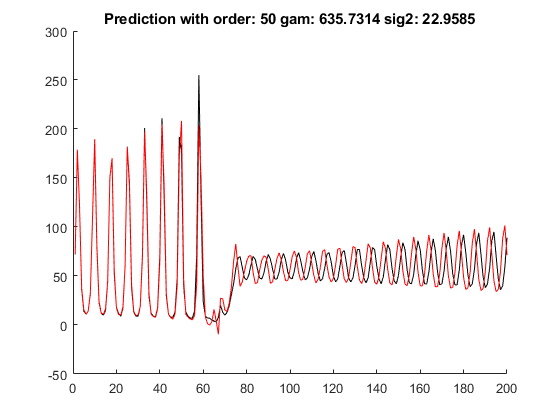

% 
% 
% 
Xs = Z(end - opt_order + 1:end , 1);

X = windowize(Z, 1:(opt_order + 1));    
Y = X(:, end);
X = X(:, 1:opt_order);

nb = 200;
prediction = predict({X, Y, 'f', opt_gam, opt_sig2,'RBF_kernel'}, Xs, nb);

figure;

hold on;
plot_title = ['Prediction with order: ' num2str(opt_order) ' gam: ' num2str(opt_gam) ' sig2: ' num2str(opt_sig2)];
title(plot_title);
plot(Ztest, 'k');
plot(prediction, 'r');
hold off;